# Assignment 8 ModSim

#### By Alexander Rambech

### Task 1

**a)**

For functionality in the MATLAB live script the actual Newton's Method function is implemented at the bottom of the file. The code within the functions looks like:

tolerance = 0.0001;
iter = 7;
x = zeros(length(x_0), iter);
x(:, 1) = x_0;
xn = x_0;
i = 1;
size(xn)
a = f(xn);
while norm(a,Inf) > tolerance && iter > i
   x(:, i+1) = x(:, i) - J(x(:, i))\f(x(:, i));
   i = i + 1;
end
clear variables

**b)**

% Equation
x = sym('x', [2 1]);
f = [x(1)*x(2) - 2; (x(1)^4)/4 + (x(2)^3)/3 - 1];

% Initial conditions
x_0 = [-1; -1];
iter = 7;

f_J = jacobian(f, x);

f = matlabFunction(f, 'vars', {x});
f_J = matlabFunction(f_J, 'vars', {x});

Newton = NewtonsMethod(f, f_J, x_0, iter);

% Find inf-norm residuals
Residuals = zeros(1, length(Newton));
for i=1:length(Residuals)
    Residuals(i) = norm(f(Newton(:,i)),"Inf");
end

% Plot 
figure(1);
semilogy(Residuals)

**c)**

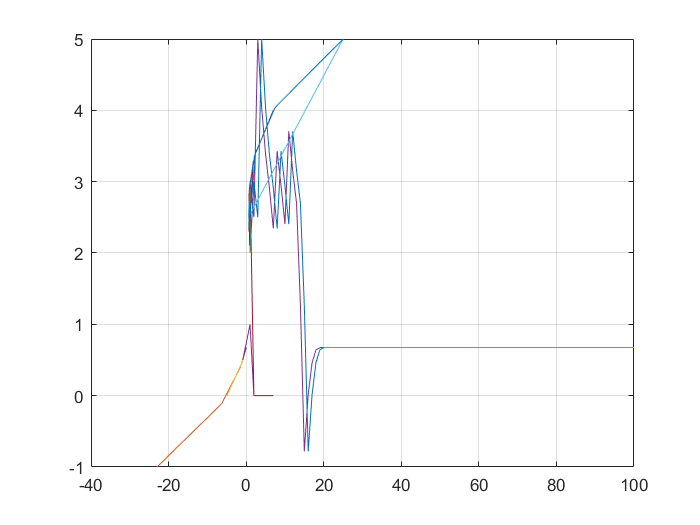

clear all;

% Initialise function
syms x;
f = x.^3 - 6*x.^2 + 11*x - 5;
x_0 = [-1 0 1 2 3 4 5]; % Trying different initial values for approximation
df = diff(f, x);
iter = 7;
temp_x = zeros(length(x_0));
est_f = zeros(length(x_0), iter);

f = matlabFunction(f, "vars", {x});
df = matlabFunction(df, "vars", {x});
for i=1:length(x_0)
    temp_x(i, :) = NewtonsMethod(f, df, x_0(i), iter);
    est_f(i, :) = f(temp_x(i, :));
end

% Plot 
figure(2);
hold on;
grid on;
for i=1:length(x_0)
   plot(est_f(i, :), temp_x(i, :))
end

We see that noen of the different initial values give a proper approximation of the equation, but we can maybe see some hits as what the function might be, given that we put these together. $-1$ seems to be the best estimate of the function during this testing. I am not quite certain what improvements can be done to the function. There might be some probelms around 3.

**d)**

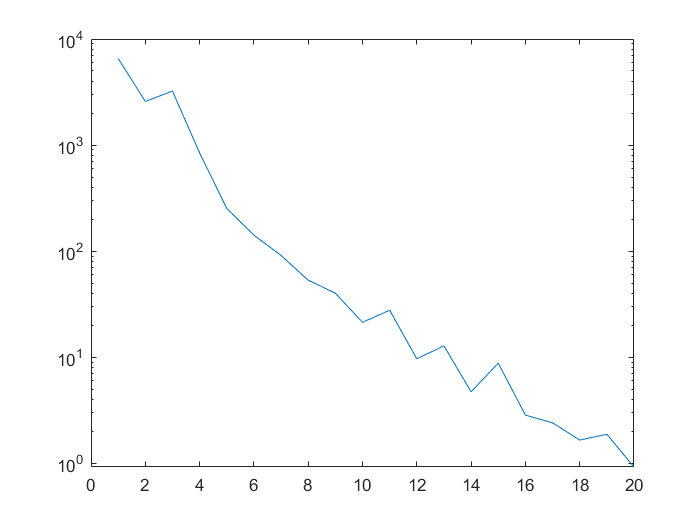

clear all;
% Equation
x = sym('x', [2 1]);
f = 100*(x(2) - x(1))^2 + (x(1) - 1)^4;

% Initial conditions
x_0 = [10; 10];
iter = 20;

f_J = jacobian(f, x);

f = matlabFunction(f, 'vars', {x});
f_J = matlabFunction(f_J, 'vars', {x});

Newton = NewtonsMethod(f, f_J, x_0, iter);

% Find inf-norm residuals
Residuals = zeros(1, length(Newton));
for i=1:length(Residuals)
    Residuals(i) = norm(f(Newton(:,i)),"Inf");
end

% Plot 
figure(3);
semilogy(Residuals)

## Newton's method function

function x = NewtonsMethod(f, J, x_0, iter)
   tolerance = 0.001;
   x = zeros(length(x_0), iter);
   x(:, 1) = x_0;
   i = 1;
   while norm(f(x_0),Inf) > tolerance && iter > i
       x(:, i+1) = x(:, i) - J(x(:, i))\f(x(:, i));
       i = i + 1;
   end
end